Part B: Write a script to apply your function based on Euler’s method to the IVP on [0,1] with h = .1, .01, .001, 0.0005, .0001 respectively. Record the associated errh’s and use Matlab’s built-in function loglog to plot errh vs h in a log-log scale.

h = [0.1;0.01;0.001;0.0005;0.0001];
f = @(x,y)-y+sin(x);
ytrue = @(x) 1.5*exp(-x) + 0.5*(sin(x)-cos(x)); % true solution function
n = numel(h);
errh = zeros(n,1);
for i = 1:n
    errh(i) = Euler_wErr(f,0,1,1,h(i),ytrue);
end
errh

errh =    0.034963406690659
   0.003331644869342
   0.000331613176015
   0.000165763783147
   0.000033145904974


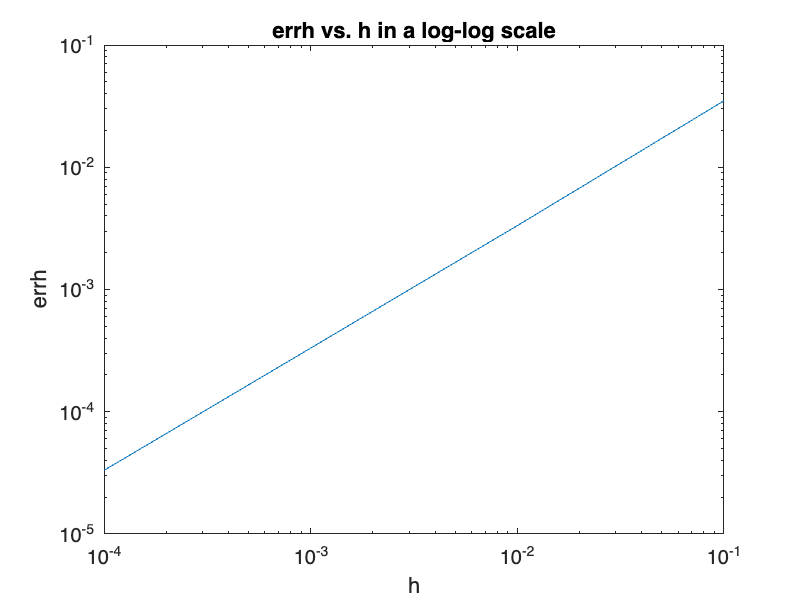

loglog(h,errh)
xlabel('h'); ylabel('errh');
title('errh vs. h in a log-log scale');

Part C -- If errh ≈ Ch, then as log10 (h) increases, log10 (errh) also increases. This can also be seen in the plot from part b.

Part D: Use Matlab’s built-in function polyfit for find the best line that fit that (log10(h), log10(errh)) data

p = polyfit(log10(h),log10(errh),1);
fprintf('Line that best fits the (log10(h),log10(errh) data is:')

Line that best fits the (log10(h),log10(errh) data is:

fprintf('log10(errh) = %g*log10(h) + %g', p(1),p(2))

log10(errh) = 1.00723*log10(h) + -0.455208